# **Case Study: Rolling Element Bearing Fault Diagnosis - Part  1**

Industrial AI & Automation by Y.K.Kim

Mod: 2024-2

## Introduction

This case study shows how to perform fault diagnosis of a rolling element bearing based on acceleration signals, especially in the presence of strong masking signals from other machine components. 

**Part 1:  Apply envelope spectrum analysis and spectral kurtosis to diagnose bearing faults**

Part 2:  Scale up to a Big Data application.

## **Problem Overview**

Localized faults in a rolling element bearing may occur in the outer race, the inner race, the cage, or a rolling element. 

**High frequency resonances** between the bearing and the response transducer are excited when the rolling elements strike a local fault on the outer or inner race, or a fault on a rolling element strikes the outer or inner race [1]. 

The following picture shows a rolling element striking a local fault at the inner race. 

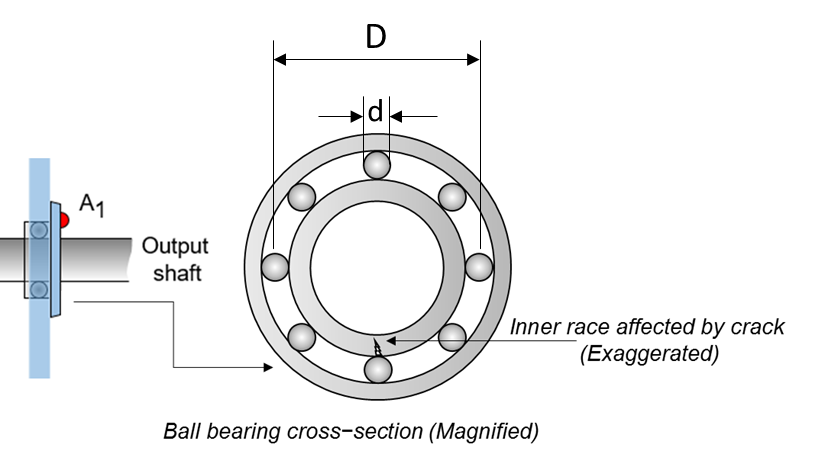

## Dataset

Machinery Failure Prevention Technology (MFPT) Challenge Data,  23 data sets collected from machines under various fault conditions. 

[Download dataset here](https://drive.google.com/file/d/11V4bhJths3vVB4_qseOhqWSCiEeGg7Uy/view?usp=sharing)

> You must save the dataset under  `/Dataset` folder

**Train data**

-  20 data sets are collected from a bearing test rig, with 3 under good conditions, 3 with outer race faults under constant load, 7 with outer race faults under various loads, and 7 with inner race faults under various loads. 

**Test data**

- 3 data sets are from real-world machines: an oil pump bearing, an intermediate speed bearing, and a planet bearing. The fault locations are unknown. 

**Variables**

Acceleration signal "gs", sampling rate "sr", shaft speed "rate", load weight "load",

Four critical frequencies representing different fault locations: ballpass frequency outer race (BPFO), ballpass frequency inner race (BPFI), fundamental train frequency (FTF), and ball spin frequency (BSF). 

- Ballpass frequency, outer race (BPFO)


$$BPFO = \frac{nf_r}{2}\left(1-\frac{d}{D}\cos \phi\right)$$


- Ballpass frequency, inner race (BPFI)


$$BPFI = \frac{nf_r}{2}\left(1+\frac{d}{D}\cos \phi\right)$$


- Fundamental train frequency (FTF), also known as cage speed


$$FTF = \frac{f_r}{2}\left(1-\frac{d}{D}\cos \phi\right)$$


- Ball (roller) spin frequency


$$BSF = \frac{D}{2d}\left[1-\left(\frac{d}{D}\cos \phi\right)^2\right]$$


As shown in the figure, $d$ is the ball diameter, $D$ is the pitch diameter. The variable $f_r$ is the shaft speed, $n$ is the number of rolling elements, $\phi$ is the bearing contact angle [1].

# 1. Feature  Extraction on Inner Race Fault

The shaft speed is constant

The impact (between parts/faults) will modulate the corresponding critical frequencies, e.g. BPFO, BPFI, FTF, BSF. 

Therefore, **the envelope signal** produced by amplitude demodulation conveys more diagnostic information that is not available from spectrum analysis of the raw signal. 

## Include path

clear all;
addpath('../../Library')

## Load Inner Race Fault Data

dataInner = load(fullfile('RollingElementBearingFaultDiagnosis-Data-master','train_data', 'InnerRaceFault_vload_1.mat'));

x_inner = dataInner.bearing.gs;
fs_inner = dataInner.bearing.sr;
t_inner = (0:length(x_inner)-1)/fs_inner;

Fs=fs_inner;
l_inner=length(x_inner);
f_inner = 0:Fs/l_inner:Fs/2;

### Time-Domain Signal

Plot  the raw inner race fault data in the time domain.

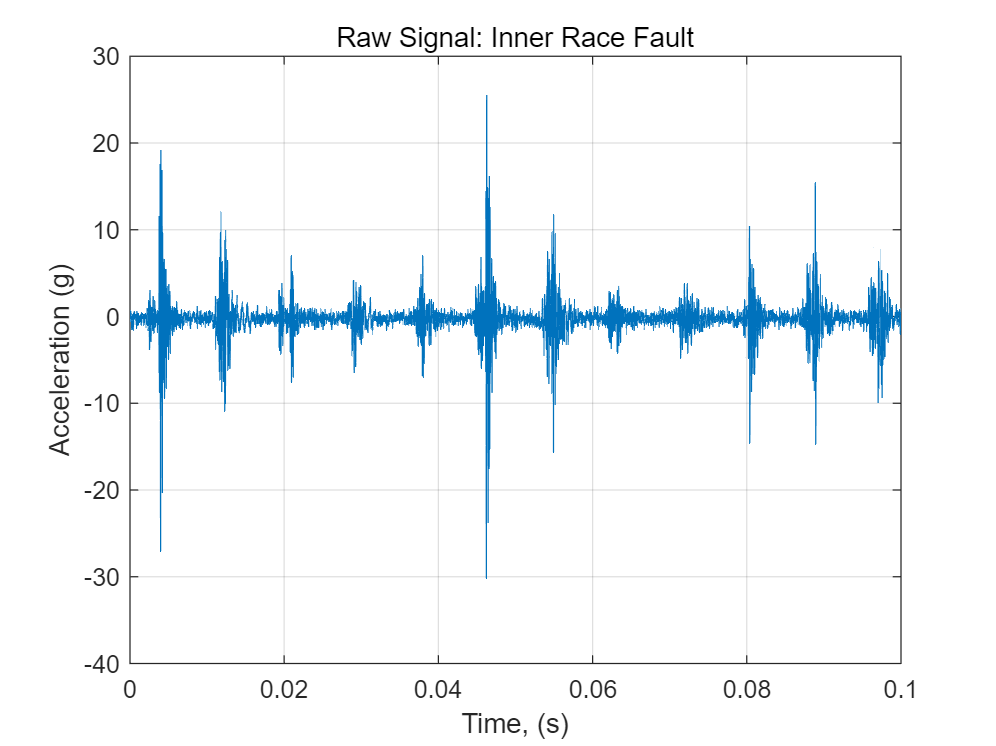

figure
plot(t_inner, x_inner); grid on;
xlabel('Time, (s)')
ylabel('Acceleration (g)')
title('Raw Signal: Inner Race Fault')
xlim([0 0.1])

Looking at the time-domain data, it is observed that the amplitude of the raw signal is modulated at a certain frequency, and the main frequency of the modulation is around 1/0.009 Hz $\approx$ 111 Hz. It is known that the frequency the rolling element hitting a local fault at the inner race, that is BPFI, is 118.875 Hz. 

This indicates that the bearing potentially has an inner race fault.

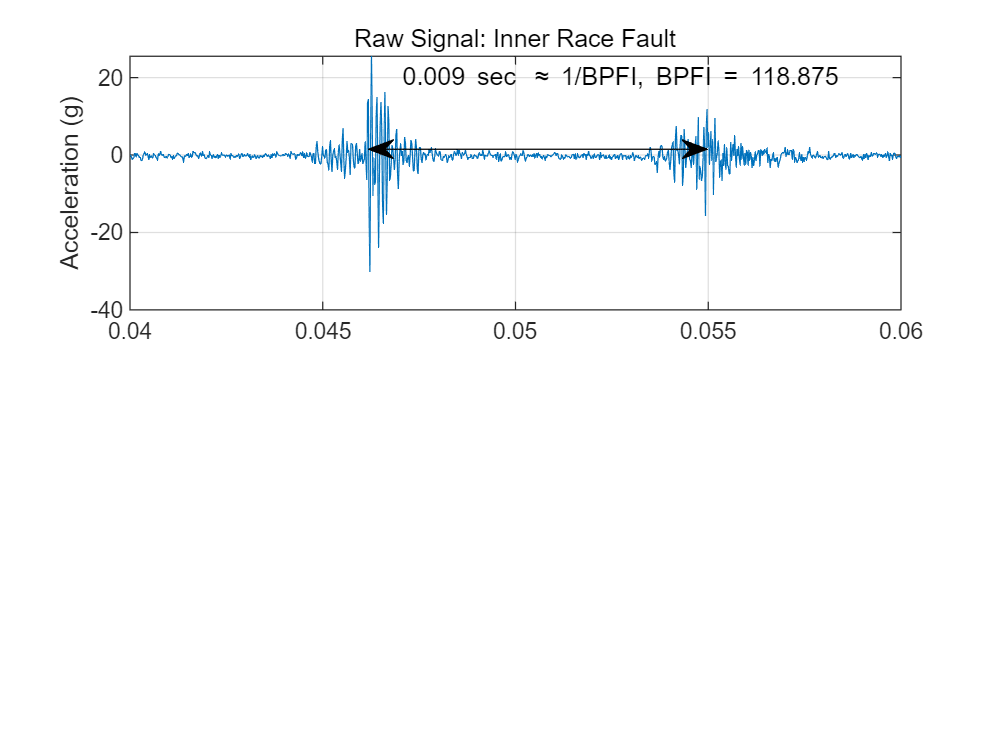

figure
subplot(2, 1, 1)
plot(t_inner, x_inner); grid on;
xlim([0.04 0.06])
title('Raw Signal: Inner Race Fault')
ylabel('Acceleration (g)')
annotation('doublearrow', [0.37 0.71], [0.8 0.8])
text(0.047, 20, ['0.009 sec \approx 1/BPFI, BPFI = ' num2str(dataInner.BPFI)])

**EXERCISE:  Kurtosis**

Calculate the kurtosis. 

Kurtosis is the fourth standardized moment of a random variable. It characterizes the impulsiveness of the signal or the heaviness of the random variable's tail. 

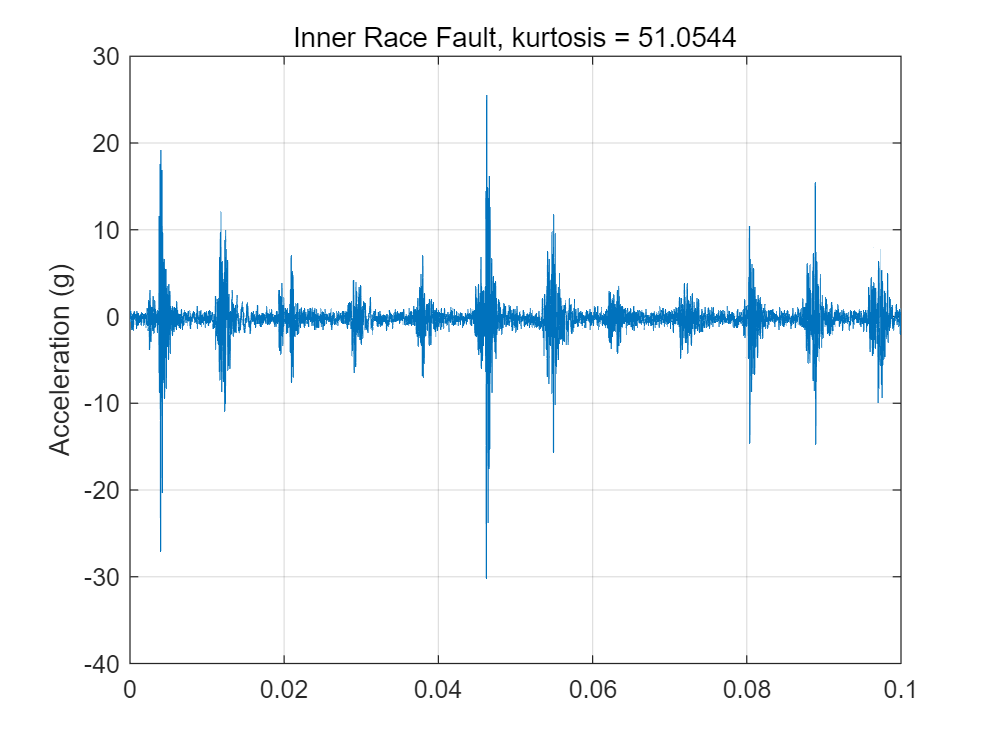

kurt_inner = kurtosis(x_inner);

% Plot
figure
plot(t_inner, x_inner); grid on;
ylabel('Acceleration (g)')
title(['Inner Race Fault, kurtosis = ' num2str(kurt_inner)])
xlim([0 0.1])

### Frequency-Domain Signal

**EXERCISE: Plot  FFT**

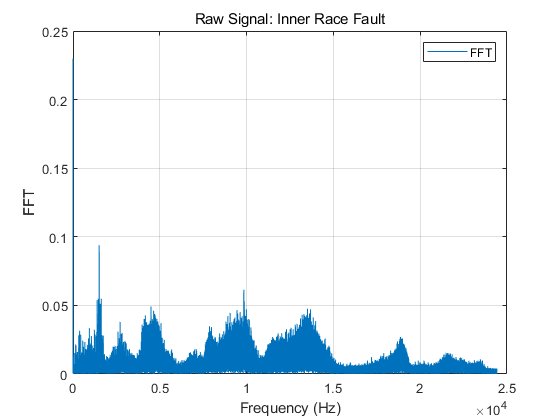

% FFT
P1=getFFT(x_inner,l_inner);


% Plot FFT
figure
plot(f_inner, P1); grid on;
xlabel('Frequency (Hz)')
ylabel('FFT')
title('Raw Signal: Inner Race Fault')
legend('FFT')

**EXERCISE: Plot  Power Spectrum **

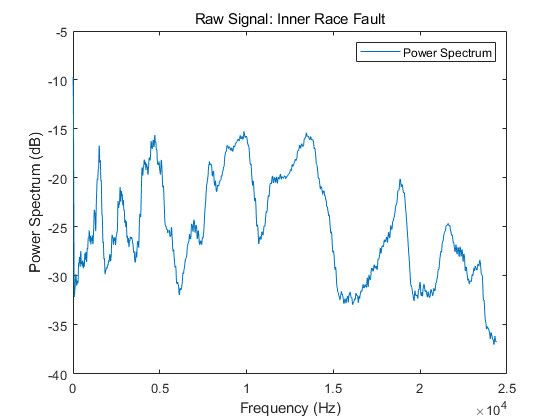

% pspectrum()  
[p_inner, fp_inner] = pspectrum(x_inner,Fs,"power");

% Plot
figure; grid on;
plot(fp_inner, 10*log10(p_inner))
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')
title('Raw Signal: Inner Race Fault')
legend('Power Spectrum')

Now zoom in the power spectrum of the raw signal in low frequency range to take a closer look at the frequency response at BPFI and its first several harmonics.

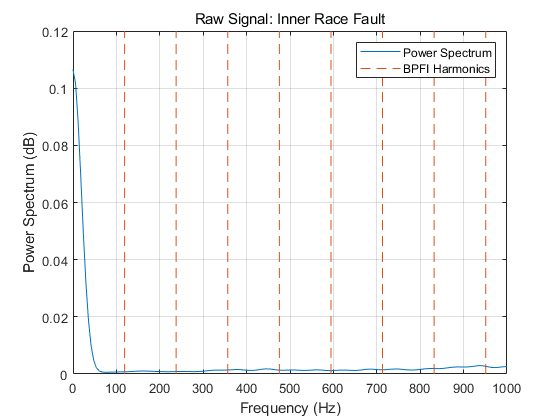

figure
plot(fp_inner, p_inner)
ncomb = 10;
helperPlotCombs(ncomb, dataInner.BPFI); grid on;
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')
title('Raw Signal: Inner Race Fault')
legend('Power Spectrum', 'BPFI Harmonics')
xlim([0 1000])

No clear pattern is visible at BPFI and its harmonics. Frequency analysis on the raw signal does not provide useful diagnosis information.

--> Use Envelop Extraction

### **EXERCISE: **Envelope Extraction

Extract the modulated amplitude, compute the envelope of the raw signal

visualize it on the bottom subplot

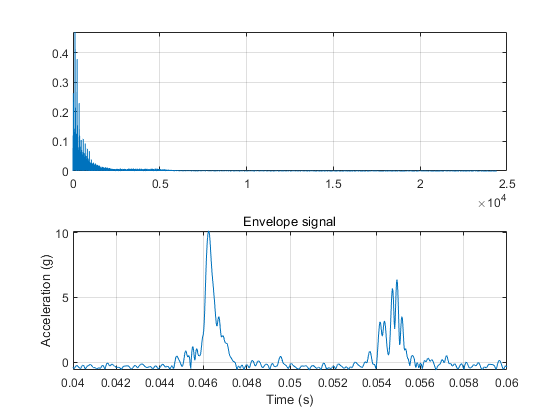

%%% YOUR CODE GOES HERE
[pEnvInner, fEnvInner, xEnvInner, tEnvInner] = envspectrum(x_inner,Fs);


% Plot
subplot(2, 1, 1)
plot(fEnvInner, pEnvInner); grid on;
xlabel('Frequency [Hz]');
ylabel('Amplitude of Signal');
subplot(2, 1, 2)
plot(tEnvInner, xEnvInner); grid on;
xlim([0.04 0.06])
xlabel('Time (s)')
ylabel('Acceleration (g)')
title('Envelope signal')

**Power Spectrum of Envelope signals **

Now compute the power spectrum of the envelope signal and take a look at the frequency response at BPFI and its harmonics.

It is shown that most of the energy is focused at BPFI and its harmonics. 

- That indicates an inner race fault of the bearing, which matches the fault type of the data.

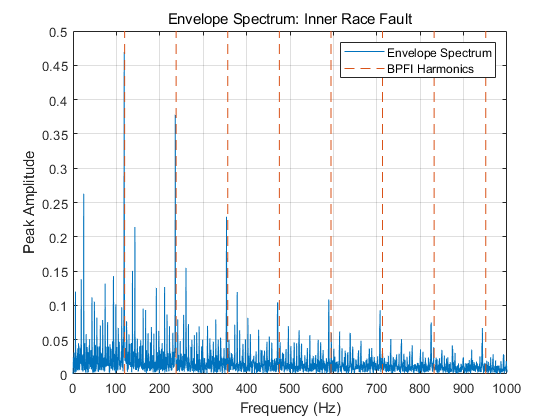

figure
plot(fEnvInner, pEnvInner)
xlim([0 1000])
ncomb = 10;
helperPlotCombs(ncomb, dataInner.BPFI)
grid on;
xlabel('Frequency (Hz)')
ylabel('Peak Amplitude')
title('Envelope Spectrum: Inner Race Fault')
legend('Envelope Spectrum', 'BPFI Harmonics')

# 2. Applying Envelope Spectrum Analysis to Normal and Outer-race classes

## Analyze Normal Data

Now repeat the same envelope spectrum analysis on normal data and outer race fault data.

dataNormal = load(fullfile('RollingElementBearingFaultDiagnosis-Data-master','train_data', 'baseline_1.mat'));

x_normal = dataNormal.bearing.gs;
l_normal= length(x_normal);
fs_normal = dataNormal.bearing.sr;
t_normal = (0:l_normal-1)/fs_normal;

Fs=fs_normal;
f = 0:Fs/l_normal:Fs/2;
[pEnvNormal, fEnvNormal,xEnvNormal, tEnvNormal] = envspectrum(x_normal, fs_normal);


### Exercise: Time-Domain Signal

Plot  the raw inner race fault data in the time domain. Analyze the signal

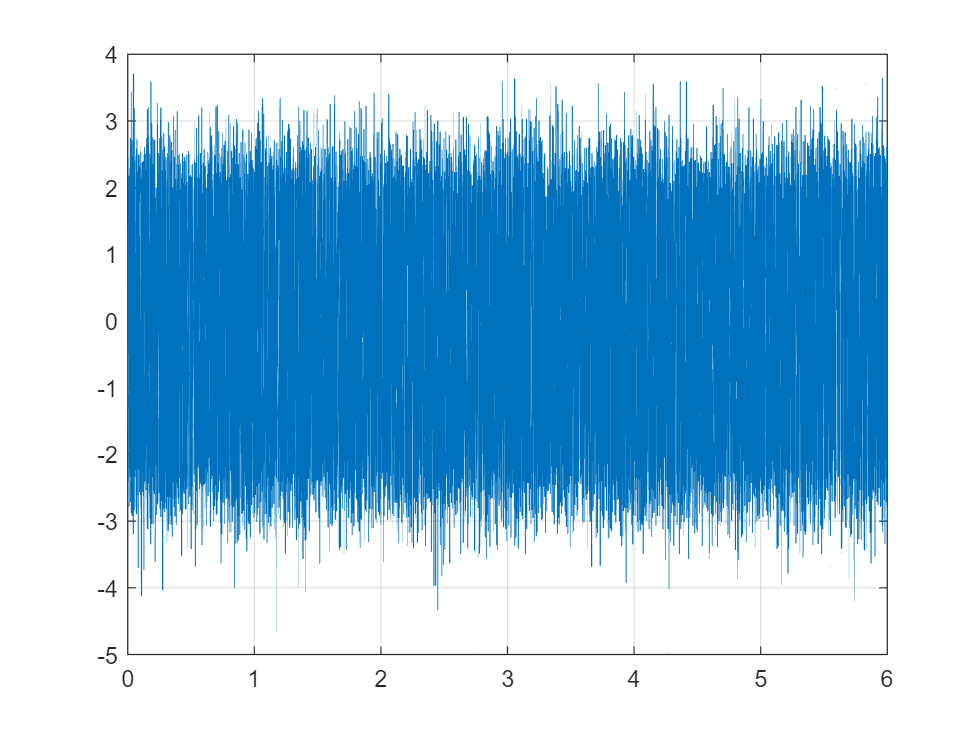

%%% YOUR CODE GOES HERE
Ts = 1/Fs;
ftime = (l_normal-1)*Ts;
time = 0:1/Fs:ftime;

figure, plot(time, x_normal);grid on; 

**Kurtosis**

Calculate the kurtosis. 

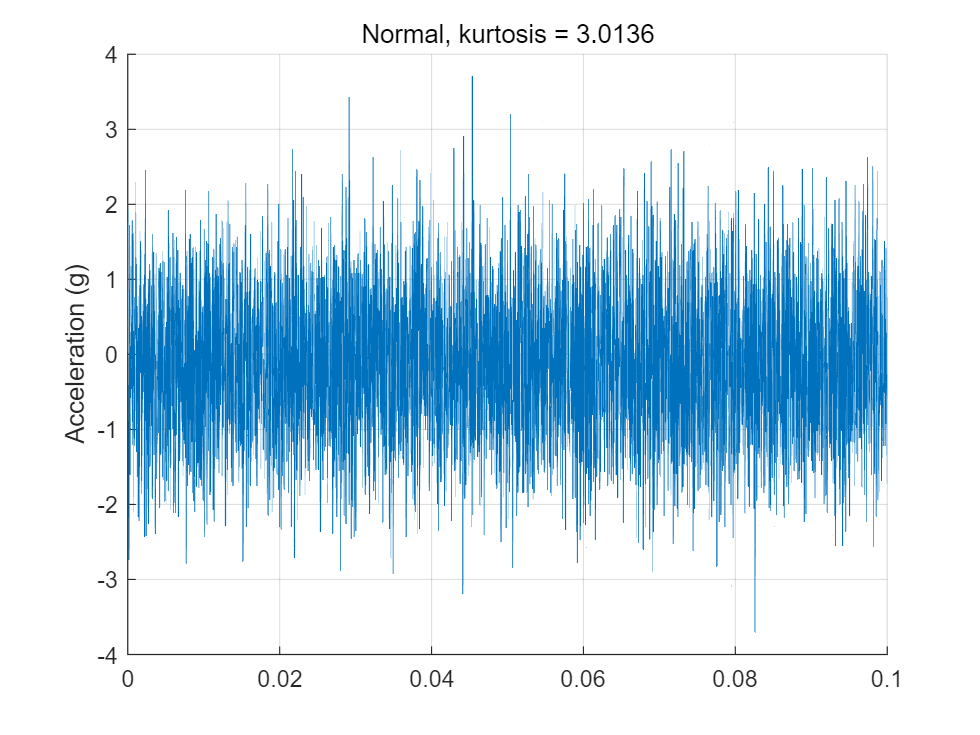

%%% YOUR CODE GOES HERE
figure; hold on; grid on;
kurt_normal = kurtosis(x_normal);
plot(t_normal, x_normal) 
ylabel('Acceleration (g)')
title(['Normal, kurtosis = ' num2str(kurt_normal)])
xlim([0 0.1])

### Exercise: Frequency-Domain Signal

**Plot  FFT**

freq_inner= 0:fs_inner/l_inner:fs_inner/2;
freq_normal = 0:fs_normal/l_normal:fs_normal/2;

P_inner = getFFT(x_inner, l_inner);
P_normal = getFFT(x_normal, l_normal);

figure, hold on; grid on;
plot(freq_normal,P_normal,'r');
plot(freq_inner,P_inner,'b');
ncomb = 10;
xlim([0 (ncomb-ncomb/2)*max([dataInner.BPFO dataInner.BPFI])]);


**Plot  Power Spectrum **

Check at BPFO and BPFI harmonics

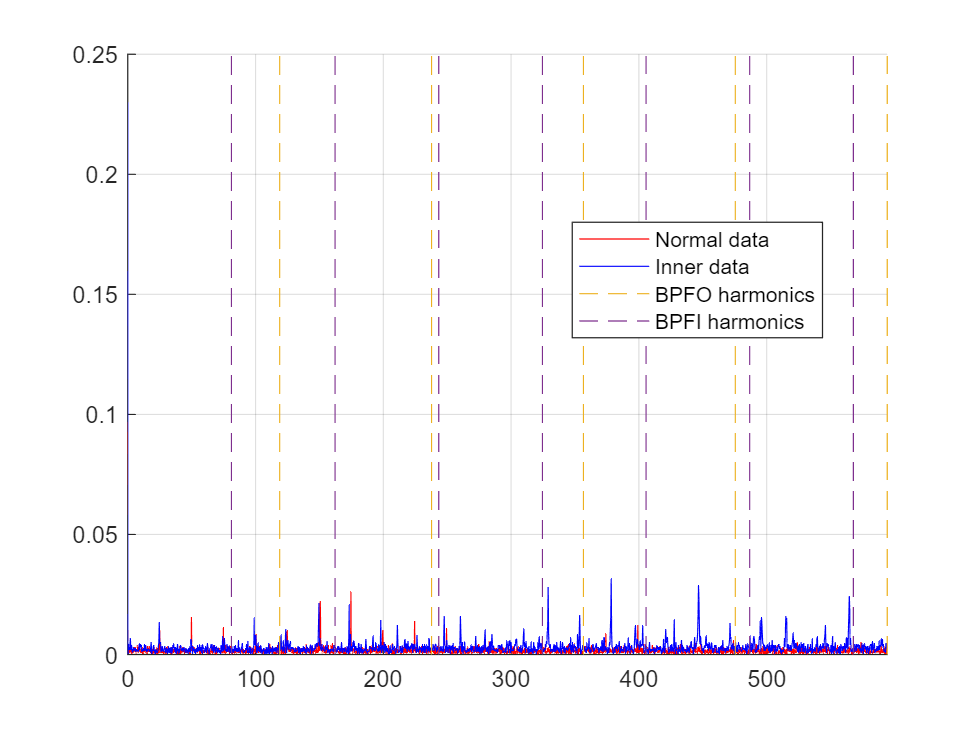

%%% YOUR CODE GOES HERE
helperPlotCombs(ncomb, [dataInner.BPFI dataInner.BPFO]);
legend('Normal data','Inner data','BPFO harmonics','BPFI harmonics');
legend('Location','best');

**Envelope Extraction**

[z_normal, inst_amp_normal] = envelopExtract(x_normal);

**Power Spectrum of Envelope signals **

Check at BPFO and BPFI harmonics

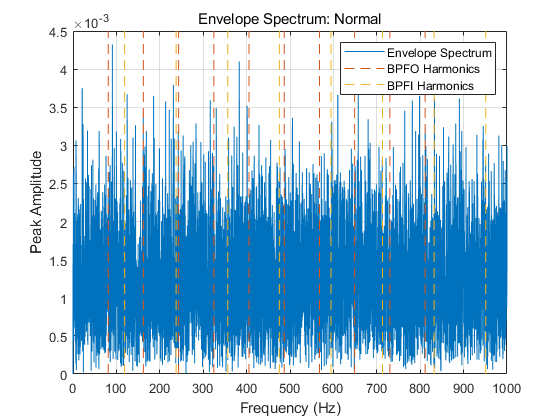

figure
plot(fEnvNormal, pEnvNormal)
ncomb = 10;
helperPlotCombs(ncomb, [dataNormal.BPFO dataNormal.BPFI]); grid on;
xlim([0 1000])
xlabel('Frequency (Hz)')
ylabel('Peak Amplitude')
title('Envelope Spectrum: Normal')
legend('Envelope Spectrum', 'BPFO Harmonics', 'BPFI Harmonics')

As expected, the envelope spectrum of a normal bearing signal does not show any significant peaks at BPFO or BPFI.

## Analyze Outer Race  Data

dataOuter = load(fullfile('RollingElementBearingFaultDiagnosis-Data-master','train_data', 'OuterRaceFault_2.mat'));

x_outer = dataOuter.bearing.gs;
fs_outer = dataOuter.bearing.sr;
l_outer = length(x_outer);
t_outer = (0:l_outer-1)/fs_outer;
freq_outer = 0:fs_outer/l_outer: fs_outer/2;
Fs = fs_outer;

For an outer race fault signal, there are no clear peaks at BPFO harmonics either. Does envelope spectrum analysis fail to differentiate bearing with outer race fault from healthy bearings? Let's take a step back and look at the signals in time domain under different conditions again.

### Exercise: Time-Domain Signal

Plot  the raw inner race fault data in the time domain. Analyze the signal

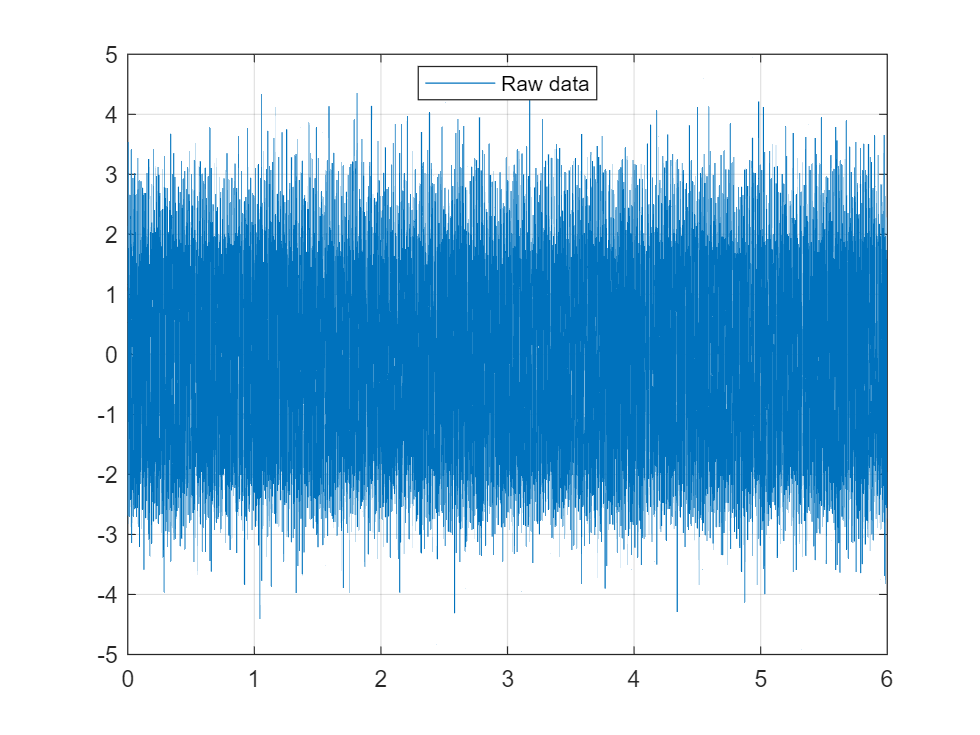

%%% YOUR CODE GOES HERE
figure
plot(t_outer, x_outer,'DisplayName','Raw data');grid on;
legend('Location','best');

**Kurtosis**

Calculate the kurtosis. 

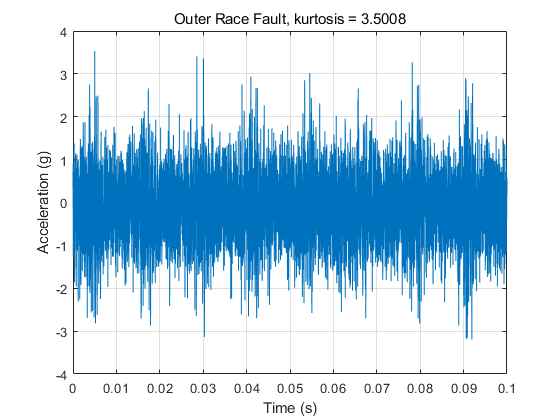

%%% YOUR CODE GOES HERE
kurt_outer = kurtosis(x_outer);
figure;
plot(t_outer, x_outer); grid on;
xlabel('Time (s)')
ylabel('Acceleration (g)')
title(['Outer Race Fault, kurtosis = ' num2str(kurt_outer)])
xlim([0 0.1])

### Exercise: Frequency-Domain Signal

**Plot  FFT**

P_outer = getFFT(x_outer,l_outer);
figure, hold on, grid on;
plot(freq_outer,P_outer);

**Plot  Power Spectrum **

Check at BPFO and BPFI harmonics

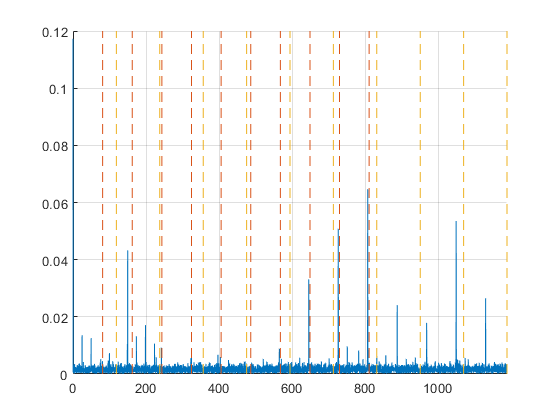

helperPlotCombs(ncomb, [dataOuter.BPFO dataOuter.BPFI]);
xlim([0 ncomb*max([dataOuter.BPFO dataOuter.BPFI])]);

**Envelope Extraction**

[z_outer, inst_amp_outer] = envelopExtract(x_outer);

**Power Spectrum of Envelope signals **

Check at BPFO and BPFI harmonics

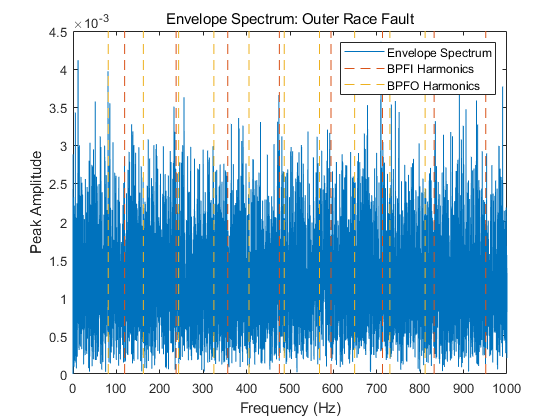

[pEnvOuter, fEnvOuter, xEnvOuter, tEnvOuter] = envspectrum(x_outer,fs_outer);

figure
plot(fEnvOuter, pEnvOuter)
ncomb = 10;
helperPlotCombs(ncomb, [dataOuter.BPFI dataOuter.BPFO])
xlim([0 1000])
xlabel('Frequency (Hz)')
ylabel('Peak Amplitude')
title('Envelope Spectrum: Outer Race Fault')
legend('Envelope Spectrum', 'BPFI Harmonics','BPFO Harmonics')

## **EXERCISE: Compare Kurtosis of three classes**

It is shown that inner race fault signal has significantly larger impulsiveness, making envelope spectrum analysis capture the fault signature at BPFI effectively.

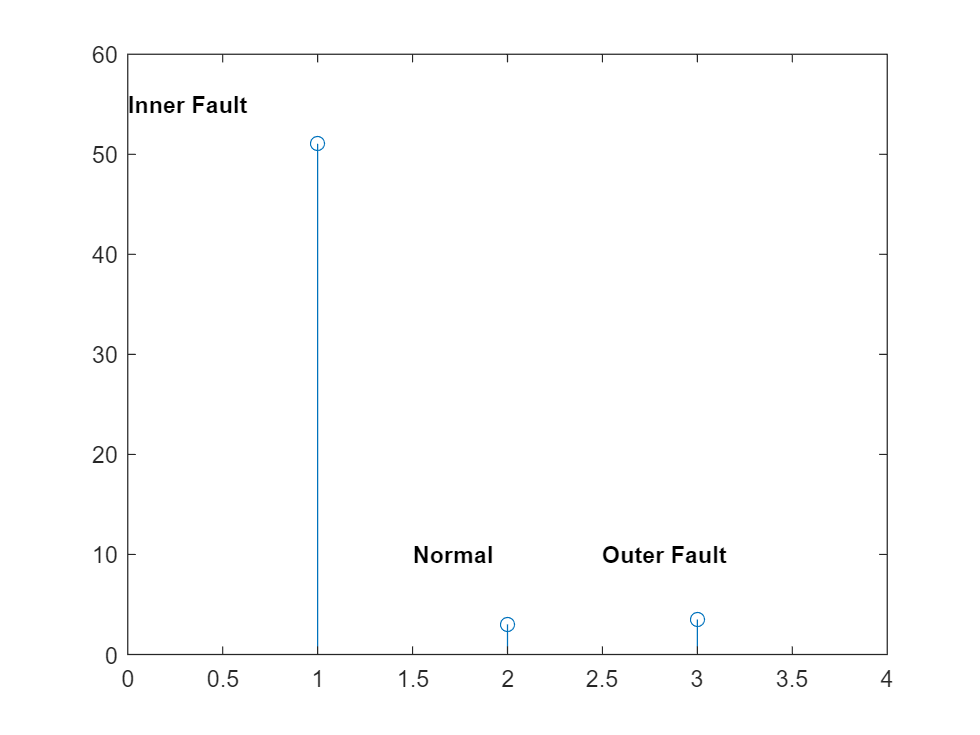

% Compare kurtosis of inner/outer/normal by plotting
kurt_result = [kurt_inner kurt_normal kurt_outer];
stem(kurt_result); xlim([0 4]); hold on;
text(0,55,'Inner Fault','FontWeight','bold');
text(1.5,10,'Normal','FontWeight','bold');
text(2.5,10,'Outer Fault','FontWeight','bold');

# 3. Analyze Kurtogram and Spectral Kurtosis on Outer-Race Class

The normal signal does not show any amplitude modulation. 

Inner race fault signal has significantly larger impulsiveness

-  making envelope spectrum analysis capture the fault signature at BPFI effectively. 

Outer race fault signal, the amplitude modulation at BPFO is slightly noticeable

- but it is masked by strong noise. 

**Extracting the impulsive signal** with amplitude modulation at BPFO (or enhancing the signal-to-noise ratio) is a key preprocessing step before envelope spectrum analysis. 

**Strategy**

- Use Spectral Kurtosis

- Extract the signal with highest kurtosis, and perform envelope spectrum analysis on the filtered signal.

## Kurtogram and Spectral Kurtosis for Band Selection on Outer-Race class

Kurtogram and spectral kurtosis compute kurtosis locally within frequency bands. 

They are powerful tools to locate the frequency band that has the highest kurtosis (or the highest signal-to-noise ratio) [2]. 

After pinpointing the frequency band with the highest kurtosis, a bandpass filter can be applied to the raw signal to obtain a more impulsive signal for envelope spectrum analysis.

**EXERCISE:  Kurtogram at level=9 on Outer-Race data**

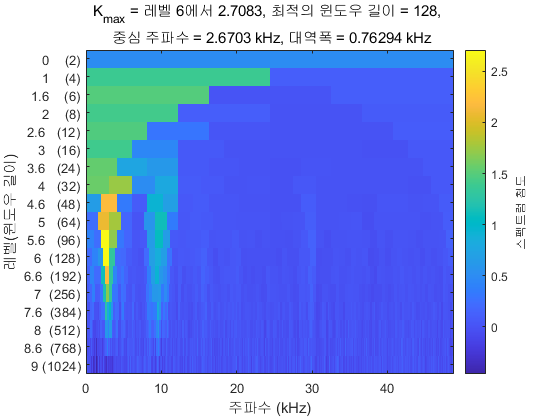

% show kurtogram at level 9
figure;
kurtogram(x_outer,fs_outer, 9);

**EXERCISE:  Obtain Optimal window Wc, BW, Fc on Outer-Race data**

[~, ~, ~, fc, wc, BW] =kurtogram(x_outer,fs_outer)

fc = 2.6703e+03

wc = 128

BW = 762.9375

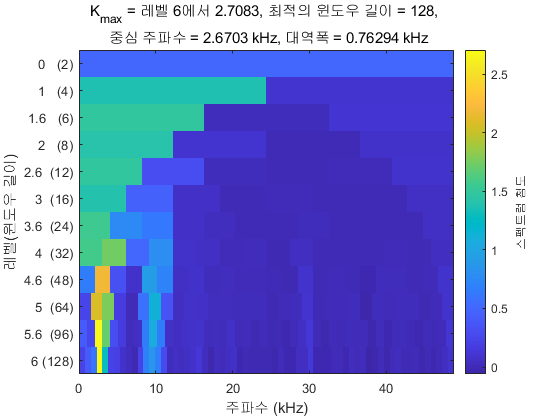

level = 6;
kurtogram(x_outer,fs_outer, level);

The kurtogram indicates that the frequency band centered at 2.67 kHz with a 0.763 kHz bandwidth has the highest kurtosis of 2.71.

**EXERCISE:  Spectral Kurtosis with  Optimal window wc on Outer-Race data**

Now use the optimal window length suggested by the kurtogram to compute the spectral kurtosis.

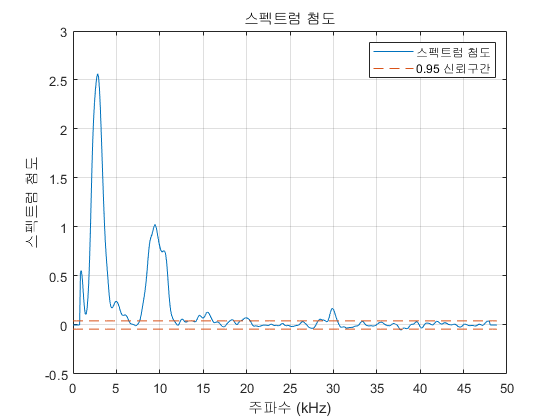

figure;
pkurtosis(x_outer, fs_outer,128);

To visualize the frequency band on a spectrogram, compute the spectrogram and place the spectral kurtosis on the side. 

To interpret the spectral kurtosis in another way, **high spectral kurtosis values indicates high variance of power at the corresponding frequency**, which makes spectral kurtosis a useful tool to locate nonstationary components of the signal [3].

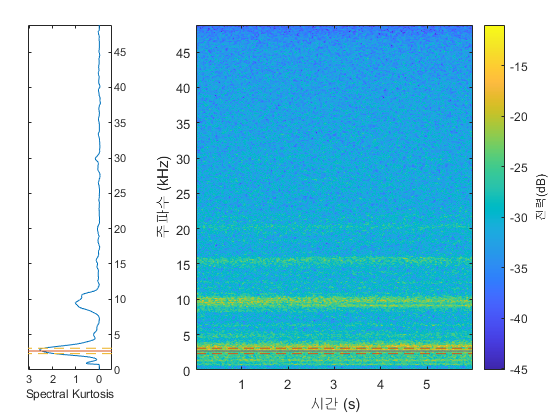

figure;
helperSpectrogramAndSpectralKurtosis(x_outer, fs_outer, level)

## Apply bandpass filtering 

By bandpass filtering the signal with the suggested center frequency and bandwidth, the kurtosis can be enhanced and the modulated amplitude of the outer race fault can be retrieved.

% Design bandpass filter
bpf = designfilt('bandpassfir', 'FilterOrder', 200, 'CutoffFrequency1', fc-BW/2, ...
    'CutoffFrequency2', fc+BW/2, 'SampleRate', fs_outer);

% Apply bandpass filter
xOuterBpf = filter(bpf, x_outer);

% Calculate Kurtosis
kurtOuterBpf = kurtosis(xOuterBpf);

% Apply bandpass filtered envelope spectrum
[pEnvOuterBpf, fEnvOuterBpf, xEnvOuterBpf, tEnvBpfOuter] = envspectrum(x_outer, fs_outer, ...
    'FilterOrder', 200, 'Band', [fc-BW/2 fc+BW/2]);


Plot band-pass applied envelop spectrum and kurtosis

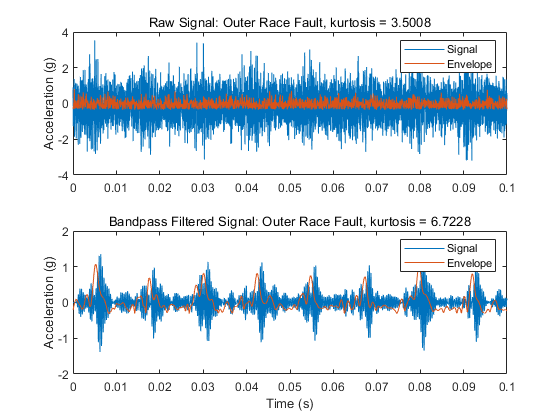

figure
subplot(2, 1, 1)
plot(t_outer, x_outer, tEnvOuter, xEnvOuter)
ylabel('Acceleration (g)')
title(['Raw Signal: Outer Race Fault, kurtosis = ', num2str(kurt_outer)])
xlim([0 0.1])
legend('Signal', 'Envelope')

subplot(2, 1, 2)
plot(t_outer, xOuterBpf, tEnvBpfOuter, xEnvOuterBpf)
ylabel('Acceleration (g)')
xlim([0 0.1])
xlabel('Time (s)')
title(['Bandpass Filtered Signal: Outer Race Fault, kurtosis = ', num2str(kurtOuterBpf)])
legend('Signal', 'Envelope')

It can be seen that the kurtosis value is increased after bandpass filtering.

 Now visualize the envelope signal in frequency domain.

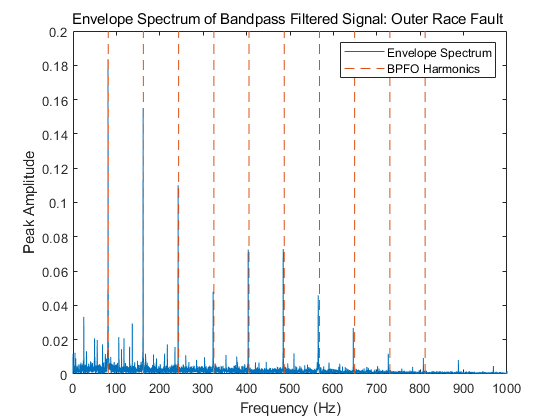

figure
plot(fEnvOuterBpf, pEnvOuterBpf);
ncomb = 10;
helperPlotCombs(ncomb, dataOuter.BPFO)
xlim([0 1000])
xlabel('Frequency (Hz)')
ylabel('Peak Amplitude')
title('Envelope Spectrum of Bandpass Filtered Signal: Outer Race Fault ')
legend('Envelope Spectrum', 'BPFO Harmonics')

It is shown that by bandpass filtering the raw signal with the frequency band suggested by kurtogram and spectral kurtosis, the envelope spectrum analysis is able to reveal the fault signature at BPFO and its harmonics.

# 4. Analyze Kurtogram and Spectral Kurtosis on Inner-Race and Normal Class

## Exercise

1) Repeat  Kurtogram/Spectral Kurtosis & Applying bandpass filtering  for Normal and Outer Race Data

2) Analyze how features are now more clearly visible after preprocessing.

### Normal data

- Kurtogram and Spectral Kurtosis for Band Selection

- Apply bandpass filtering 

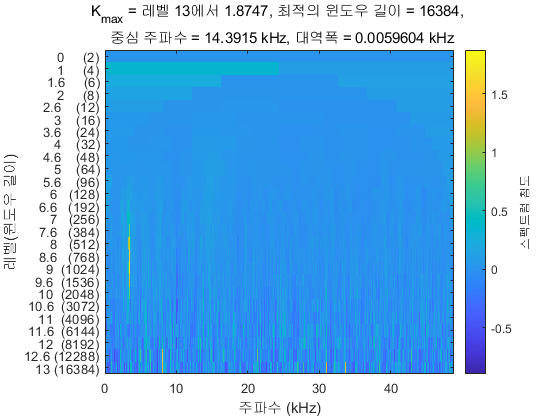

figure;
level = 13;
kurtogram(x_normal,fs_normal,13);

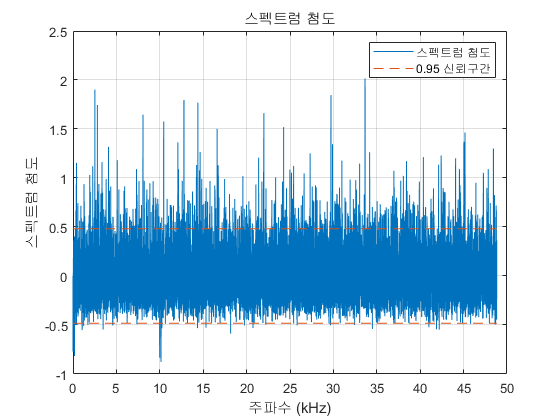

figure;
pkurtosis(x_normal, fs_normal,16384);

[~, ~, ~, fc, wc, BW] =kurtogram(x_normal,fs_normal)

fc = 1.4392e+04

wc = 16384

BW = 5.9604


bpf = designfilt('bandpassfir', 'FilterOrder', 200, 'CutoffFrequency1', fc-BW/2, ...
    'CutoffFrequency2', fc+BW/2, 'SampleRate', fs_normal);

x_normalBpf = filter(bpf, x_normal);

kurtNormalBpf = kurtosis(x_normalBpf);

[pEnvNormalBpf, fEnvNormalBpf, xEnvNormalBpf, tEnvBpfNormal] = envspectrum(x_normal, fs_normal, ...
    'FilterOrder', 200, 'Band', [fc-BW/2 fc+BW/2]);

**Plot Time-domain signals (Raw & Band-Pass Filtered)**

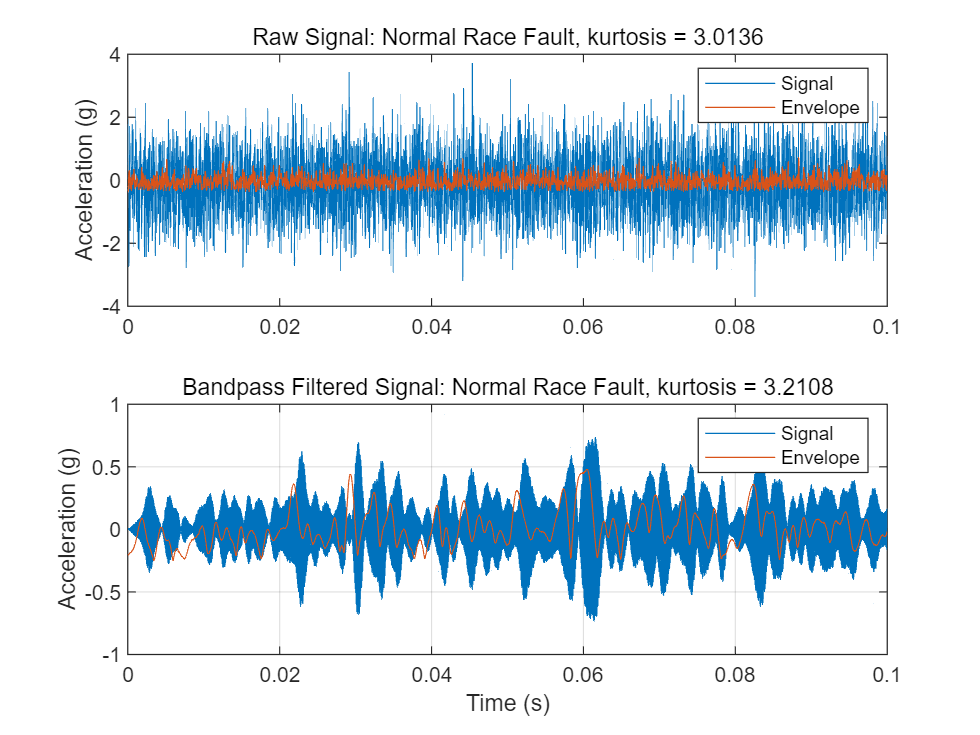

figure; hold on; grid on;
subplot(2, 1, 1)
plot(t_normal, x_normal, tEnvNormal, xEnvNormal)
ylabel('Acceleration (g)')
title(['Raw Signal: Normal Race Fault, kurtosis = ', num2str(kurt_normal)])
xlim([0 0.1])
legend('Signal', 'Envelope')

subplot(2, 1, 2)
plot(t_normal, x_normalBpf, tEnvBpfNormal, xEnvNormalBpf); hold on; grid on;
ylabel('Acceleration (g)')
xlim([0 0.1])
xlabel('Time (s)')
title(['Bandpass Filtered Signal: Normal Race Fault, kurtosis = ', num2str(kurtNormalBpf)])
legend('Signal', 'Envelope')

### Inner Race data

- Kurtogram and Spectral Kurtosis for Band Selection

- Apply bandpass filtering 

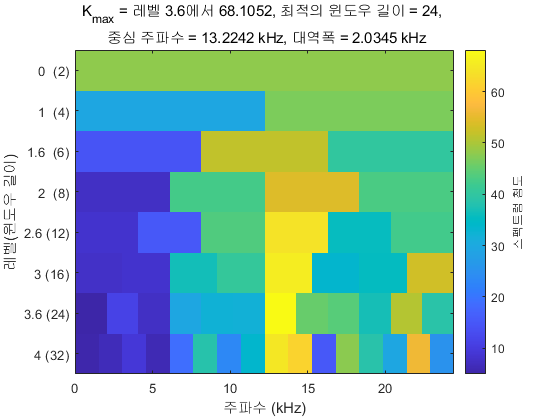

figure; 
level = 4;
kurtogram(x_inner,fs_inner,4);

레벨은 정수형에서만 정의된다. 따라서 3.6의 레벨을 4로 근사하여 도시하였다.

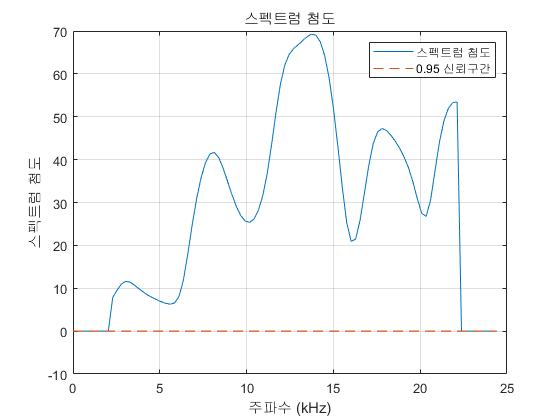

figure;
pkurtosis(x_inner, fs_inner,24)

[~, ~, ~, fc, wc, BW] =kurtogram(x_inner,fs_inner)

fc = 1.3733e+04

wc = 48

BW = 1.0173e+03

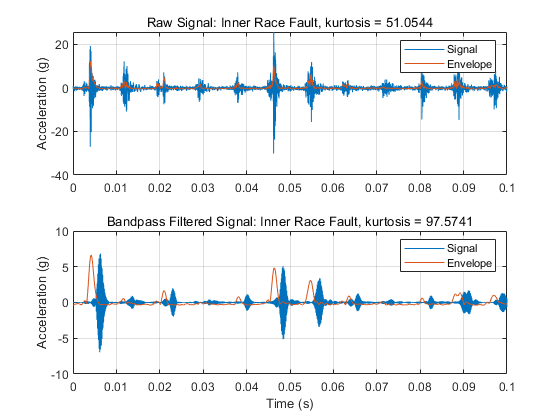

bpf = designfilt('bandpassfir', 'FilterOrder', 200, 'CutoffFrequency1', fc-BW/2, ...
    'CutoffFrequency2', fc+BW/2, 'SampleRate', fs_inner);

x_innerBpf = filter(bpf, x_inner);

kurtInnerBpf = kurtosis(x_innerBpf);

[pEnvInnerBpf, fEnvInnerBpf, xEnvInnerBpf, tEnvBpfInner] = envspectrum(x_inner, fs_inner, ...
    'FilterOrder', 200, 'Band', [fc-BW/2 fc+BW/2]);

figure; hold on; grid on;
subplot(2, 1, 1)
plot(t_inner, x_inner, tEnvInner, xEnvInner); grid on;
ylabel('Acceleration (g)')
title(['Raw Signal: Inner Race Fault, kurtosis = ', num2str(kurt_inner)])
xlim([0 0.1])
legend('Signal', 'Envelope')

subplot(2, 1, 2)
plot(t_inner, x_innerBpf, tEnvBpfInner, xEnvInnerBpf); hold on; grid on;
ylabel('Acceleration (g)')
xlim([0 0.1])
xlabel('Time (s)')
title(['Bandpass Filtered Signal: Inner Race Fault, kurtosis = ', num2str(kurtInnerBpf)])
legend('Signal', 'Envelope')

## Summary

This example shows how to use kurtogram, spectral kurtosis and envelope spectrum to identify different types of faults in rolling element bearings. 

## References

[1] Randall, Robert B., and Jerome Antoni. "Rolling element bearing diagnostics—a tutorial." *Mechanical Systems and Signal Processing*. Vol. 25, Number 2, 2011, pp. 485–520.

[2] Antoni, Jérôme. "Fast computation of the kurtogram for the detection of transient faults." *Mechanical Systems and Signal Processing*. Vol. 21, Number 1, 2007, pp. 108–124.

[3] Antoni, Jérôme. "The spectral kurtosis: a useful tool for characterising non-stationary signals." *Mechanical Systems and Signal Processing*. Vol. 20, Number 2, 2006, pp. 282–307.

[4] Bechhoefer, Eric. "Condition Based Maintenance Fault Database for Testing Diagnostics and Prognostic Algorithms." 2013. [https://mfpt.org/fault-data-sets/](https://mfpt.org/fault-data-sets/)

## Helper Functions

function bearingFeatureExtraction(ensemble)
% Extract condition indicators from bearing data
data = read(ensemble);
x = data.gs{1};
fs = data.sr;

% Critical Frequencies
BPFO = data.BPFO;
BPFI = data.BPFI;

level = 9;
[~, ~, ~, fc, ~, BW] = kurtogram(x, fs, level);

% Bandpass filtered Envelope Spectrum
[pEnvpBpf, fEnvBpf] = envspectrum(x, fs, 'FilterOrder', 200, 'Band', [max([fc-BW/2 0]) min([fc+BW/2 0.999*fs/2])]);
deltaf = fEnvBpf(2) - fEnvBpf(1);

BPFIAmplitude = max(pEnvpBpf((fEnvBpf > (BPFI-5*deltaf)) & (fEnvBpf < (BPFI+5*deltaf))));
BPFOAmplitude = max(pEnvpBpf((fEnvBpf > (BPFO-5*deltaf)) & (fEnvBpf < (BPFO+5*deltaf))));

writeToLastMemberRead(ensemble, table(BPFIAmplitude, BPFOAmplitude, 'VariableNames', {'BPFIAmplitude', 'BPFOAmplitude'}));
end